##     SETUP

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%% Effects semantic diversity and frequency in word recognition %%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Preparation
clear all;

%% Parameters

    % the maximum activation
        Fmax=1;
    % the minimum activation
        Fmin=0;
    % the resting activation level
        rest=0;
    % semantic layer decay
        decay1=0.1;
    % word layer decay
        decay2=0.02;
    % number of time steps
        step=100;
    % external input/input constant
        ic=0.001;
    % word to word inhibition
        inhW=0.001;
    % semantic inhibition
        inhS=0.0005;
    % word and semantics excitation (forward and backward)
        extf=0.03;
        extb=0.03;
    % decision threshold
        thresh=0.4;
    % weights within semantics layer
        % creates "WLR" and "WLR1"
        weightsemCurt4;

ev = 0.0520

fv = 0.0360

gv = 0.0240

    % frequency factors
        HF1=1.36;
        HF2=1.15;
        LF1=0.71;
        LF2=0.51;

##    MODELS

%%%%%%%%%%%%%%% High SemD, High Freq target %%%%%%%%%%%%%%%%

% semantics layer
    SL1=zeros(step,70);
% word layer; 
    WL1=zeros(step,11);
    % these layer matrices fill in with the activation for each unit at each step

% weights btween Semantics and Word Layer
   WLW=zeros(11,70);
    WLW(1,1:10)=HF1; 
    WLW(2,7:10)=HF2;WLW(2,11:16)=HF2;
    WLW(3,7:10)=HF2;WLW(3,17:22)=HF2;
    WLW(4,7:10)=HF2;WLW(4,23:28)=HF2;
    WLW(5,7:10)=HF2;WLW(5,29:34)=HF2;
    WLW(6,7:10)=HF2;WLW(6,35:40)=HF2;
    WLW(7,7:10)=HF2;WLW(7,41:46)=HF2;
    WLW(8,7:10)=HF2;WLW(8,47:52)=HF2;
    WLW(9,7:10)=HF2;WLW(9,53:58)=HF2;
    % WLW(10,7:10)=HF2;WLW(10,59:64)=HF2;
    % WLW(11,7:10)=HF2;WLW(11,65:70)=HF2;

    WLW5=extf*WLW

WLW5 =     0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

    WLW3=extb*WLW

WLW3 =     0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345    0.0345         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

     
% inhibitory weights
    WINWL=ones(11,11);
    WINWL=inhW*WINWL;
    for j=1:11
        WINWL(j,j)=0;
    end;
    
    WINSL=ones(70,70);
    WINSL=inhS*WINSL;
    for j=1:70
        WINSL(j,j)=0;
    end;

%initialization of cross-entropy value
    en1=zeros(step,1);

% target
    target=zeros(1,70);
    target(1:10)=1;

% cross-entroy value for the first (0) time step
    en1(1)=cee(target,SL1(1,:));

% input
    input=zeros(1,11);
    input(1)=ic;


for i=1:step-1
    
    SL1(i+1,:)=((WLW3'*WL1(i,:)')'+(WLRHD*SL1(i,:)')'-(WINSL*inhkernel3(SL1(i,:)'))'); % semantics layer net input
        % for the next row of SL (next step), the input is the forward activation of the word layer plus
        % the excitatory/inhibitory inputs within the semantic layer relative to the current activation
    
    WL1(i+1,:)=((WLW5*SL1(i,:)')')+input%-(WINWL*inhkernel3(WL1(i,:)'))'; % word layer net input
        % for the next row of WL (next step), the input is the backward activation of the semantic layer plus
        % the sigmoid inhibitory effects within the word layer relative to the current activation plus
        % the current input activation (constant)
 
    SL1(i+1,:)=SL1(i,:)... % change unit activations in semantic layer
        +(SL1(i+1,:)>0).*((Fmax-SL1(i,:)).*SL1(i+1,:)-decay1.*(SL1(i,:)-rest))... % if net input>0
        +(SL1(i+1,:)<=0).*((SL1(i,:)-Fmin).*SL1(i+1,:)-decay1.*(SL1(i,:)-rest));  % if net input<=0
    
    WL1(i+1,:)=WL1(i,:)... % change unit activations in word layer
        +(WL1(i+1,:)>0).*((Fmax-WL1(i,:)).*WL1(i+1,:)-decay2.*(WL1(i,:)-rest))...
        +(WL1(i+1,:)<=0).*((WL1(i,:)-Fmin).*WL1(i+1,:)-decay2.*(WL1(i,:)-rest));   
    
    SL1(i+1,:)=max(SL1(i+1,:),0); % set minimum value to 0, just in case
    WL1(i+1,:)=max(WL1(i+1,:),0);
    
    SL1(i+1,:)=min(SL1(i+1,:),1); % set maximum value to 1
    WL1(i+1,:)=min(WL1(i+1,:),1);
    
    en1(i+1)=cee(target,SL1(i+1,:)); % updating cross entropy value, our measure of the model's success
    % en3(i+1)=cee(target3,SL(i+1,:)); % looking at a non-target value
    
end;

WL1 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL1 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0012    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0012    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0014    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

WL1 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0049    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0060    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
    0.0071    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002         0         0
    0.0083    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003         0      

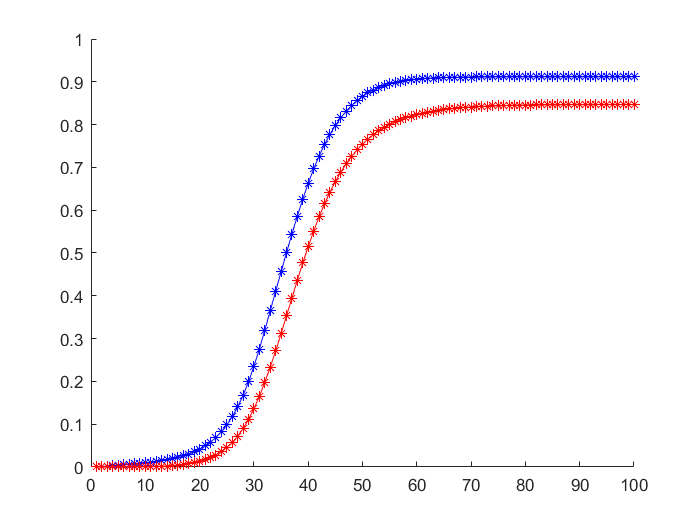


% normalizating the cross-entropy value
    en1=en1/max(en1);

% reaction time
    [peak1,t1]=find_peak_min_new(en1,thresh);
    
% plot word activation
    figure;
    hold on;
    plot(WL1(1:step,1),'b-*'); % target
    plot(WL1(1:step,2),'r-*'); % related word
    hold off;

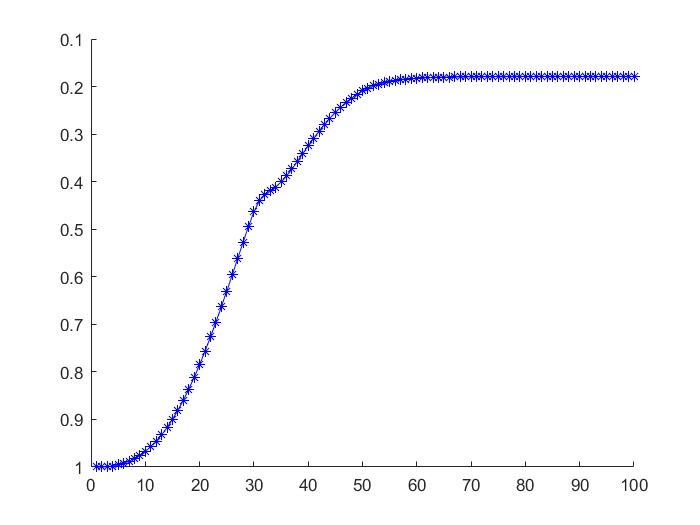


% plot semantic activation
    figure;
    hold on;
    plot(en1(1:step),'b-*'); % target
    set(gca, 'YDir','reverse')
    hold off;


%%%%%%%%%%%%%%% High SemD, Low Freq target %%%%%%%%%%%%%%%%

% semantics layer
    SL2=zeros(step,70);
% word layer; 
    WL2=zeros(step,11);
    % these layer matrices fill in with the activation for each unit at each step

% weights btween Semantics and Word Layer
   WLW=zeros(11,70);
    WLW(1,1:10)=LF1; 
    WLW(2,7:10)=LF2;WLW(2,11:16)=LF2;
    WLW(3,7:10)=LF2;WLW(3,17:22)=LF2;
    WLW(4,7:10)=LF2;WLW(4,23:28)=LF2;
    WLW(5,7:10)=LF2;WLW(5,29:34)=LF2;
    WLW(6,7:10)=LF2;WLW(6,35:40)=LF2;
    WLW(7,7:10)=LF2;WLW(7,41:46)=LF2;
    WLW(8,7:10)=LF2;WLW(8,47:52)=LF2;
    WLW(9,7:10)=LF2;WLW(9,53:58)=LF2;
    % WLW(10,7:10)=LF2;WLW(10,59:64)=LF2;
    % WLW(11,7:10)=LF2;WLW(11,65:70)=LF2;

    WLW5=extf*WLW

WLW5 =     0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

    WLW3=extb*WLW

WLW3 =     0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

     
% inhibitory weights
    WINWL=ones(11,11);
    WINWL=inhW*WINWL;
    for j=1:11
        WINWL(j,j)=0;
    end;
    
    WINSL=ones(70,70);
    WINSL=inhS*WINSL;
    for j=1:70
        WINSL(j,j)=0;
    end;

%initialization of cross-entropy value
    en2=zeros(step,1);

% target
    target=zeros(1,70);
    target(1:10)=1;

% cross-entroy value for the first (0) time step
    en2(1)=cee(target,SL2(1,:));

% input
    input=zeros(1,11);
    input(1)=ic;


for i=1:step-1
    
    SL2(i+1,:)=((WLW3'*WL2(i,:)')'+(WLRHD*SL2(i,:)')'-(WINSL*inhkernel3(SL2(i,:)'))'); % semantics layer net input
        % for the next row of SL (next step), the input is the forward activation of the word layer plus
        % the excitatory/inhibitory inputs within the semantic layer relative to the current semantic activation
    
    WL2(i+1,:)=((WLW5*SL2(i,:)')')+input%-(WINWL*inhkernel3(WL2(i,:)'))'; % word layer net input
        % for the next row of WL (next step), the input is the backward activation of the semantic layer plus
        % the sigmoid inhibitory effects within the word layer relative to the current activation plus
        % the current input activation (constant)
 
    SL2(i+1,:)=SL2(i,:)... % change unit activations in semantic layer
        +(SL2(i+1,:)>0).*((Fmax-SL2(i,:)).*SL2(i+1,:)-decay1.*(SL2(i,:)-rest))... % if net input>0
        +(SL2(i+1,:)<=0).*((SL2(i,:)-Fmin).*SL2(i+1,:)-decay1.*(SL2(i,:)-rest));  % if net input<=0
    
    WL2(i+1,:)=WL2(i,:)... % change unit activations in word layer
        +(WL2(i+1,:)>0).*((Fmax-WL2(i,:)).*WL2(i+1,:)-decay2.*(WL2(i,:)-rest))...
        +(WL2(i+1,:)<=0).*((WL2(i,:)-Fmin).*WL2(i+1,:)-decay2.*(WL2(i,:)-rest));   
    
    SL2(i+1,:)=max(SL2(i+1,:),0); % set minimum value to 0, just in case
    WL2(i+1,:)=max(WL2(i+1,:),0);
    
    SL2(i+1,:)=min(SL2(i+1,:),1); % set maximum value to 1
    WL2(i+1,:)=min(WL2(i+1,:),1);
    
    en2(i+1)=cee(target,SL2(i+1,:)); % updating cross entropy value, our measure of the model's success
    
end;

WL2 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL2 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

WL2 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0039    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0067    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
    0.0076    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0      

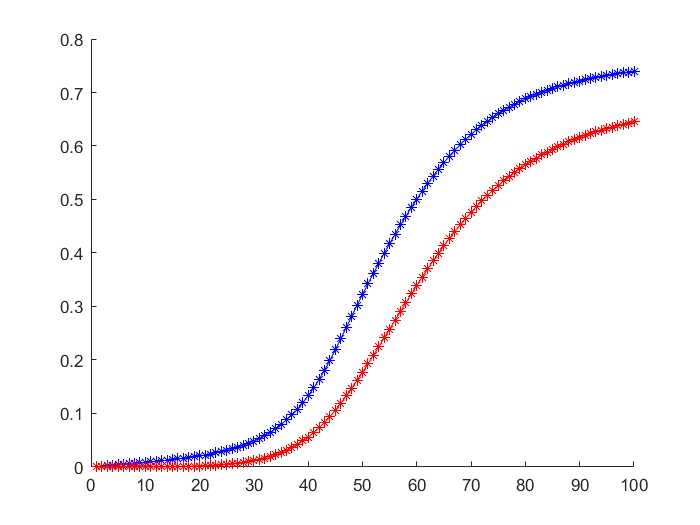


% normalizating the cross-entropy value
    en2=en2/max(en2);
    
% reaction time
    [peak2,t2]=find_peak_min_new(en2,thresh);

% plot word activation
    figure;
    hold on;
    plot(WL2(1:step,1),'b-*'); % target
    plot(WL2(1:step,2),'r-*'); % related word
    hold off;

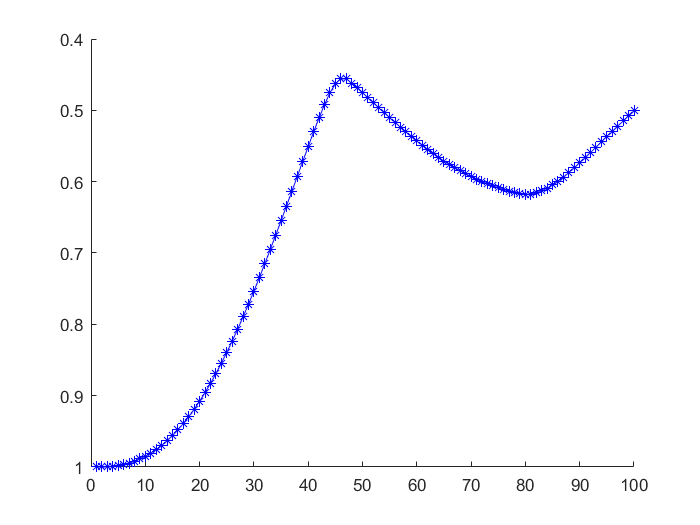


% plot semantic activation
    figure;
    hold on;
    plot(en2(1:step),'b-*'); % target
    set(gca, 'YDir','reverse')
    hold off;

    %%%%%%%%%%%%%%% Low SemD, High Freq target %%%%%%%%%%%%%%%%

% semantics layer
    SL3=zeros(step,70);
% word layer; 
    WL3=zeros(step,11);
    % these layer matrices fill in with the activation for each unit at each step

% weights btween Semantics and Word Layer
   WLW=zeros(11,70);
    WLW(1,1:10)=HF1; 
    %WLW(2,7:10)=HF2;WLW(2,11:16)=HF2;
    %WLW(3,7:10)=HF2;WLW(3,17:22)=HF2;
    %WLW(4,7:10)=HF2;WLW(4,23:28)=HF2;
    %WLW(5,7:10)=HF2;WLW(5,29:34)=HF2;
    %WLW(6,7:10)=HF2;WLW(6,35:40)=HF2;
    %WLW(7,7:10)=HF2;WLW(7,41:46)=HF2;
    %WLW(8,7:10)=HF2;WLW(8,47:52)=HF2;
    %WLW(9,7:10)=HF2;WLW(9,53:58)=HF2;
    % WLW(10,7:10)=HF2;WLW(10,59:64)=HF2;
    % WLW(11,7:10)=HF2;WLW(11,65:70)=HF2;

    WLW5=extf*WLW

WLW5 =     0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

    WLW3=extb*WLW

WLW3 =     0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

     
% inhibitory weights
    WINWL=ones(11,11);
    WINWL=inhW*WINWL;
    for j=1:11
        WINWL(j,j)=0;
    end;
    
    WINSL=ones(70,70);
    WINSL=inhS*WINSL;
    for j=1:70
        WINSL(j,j)=0;
    end;

%initialization of cross-entropy value
    en3=zeros(step,1);

% target
    target=zeros(1,70);
    target(1:10)=1;

% cross-entroy value for the first (0) time step
    en3(1)=cee(target,SL3(1,:));
    
% input
    input=zeros(1,11);
    input(1)=ic;


for i=1:step-1
    
    SL3(i+1,:)=((WLW3'*WL3(i,:)')'+(WLRLD0*SL3(i,:)')')-(WINSL*inhkernel3(SL3(i,:)'))'; % semantics layer net input
        % for the next row of SL (next step), the input is the forward activation of the word layer plus
        % the excitatory/inhibitory inputs within the semantic layer relative to the current activation
    
    WL3(i+1,:)=((WLW5*SL3(i,:)')')+input%-(WINWL*inhkernel3(WL3(i,:)'))'; % word layer net input
        % for the next row of WL (next step), the input is the backward activation of the semantic layer plus
        % the sigmoid inhibitory effects within the word layer relative to the current activation plus
        % the current input activation (constant)
 
    SL3(i+1,:)=SL3(i,:)... % change unit activations in semantic layer
        +(SL3(i+1,:)>0).*((Fmax-SL3(i,:)).*SL3(i+1,:)-decay1.*(SL3(i,:)-rest))... % if net input>0
        +(SL3(i+1,:)<=0).*((SL3(i,:)-Fmin).*SL3(i+1,:)-decay1.*(SL3(i,:)-rest));  % if net input<=0
    
    WL3(i+1,:)=WL3(i,:)... % change unit activations in word layer
        +(WL3(i+1,:)>0).*((Fmax-WL3(i,:)).*WL3(i+1,:)-decay2.*(WL3(i,:)-rest))...
        +(WL3(i+1,:)<=0).*((WL3(i,:)-Fmin).*WL3(i+1,:)-decay2.*(WL3(i,:)-rest));   
    
    SL3(i+1,:)=max(SL3(i+1,:),0); % set minimum value to 0, just in case
    WL3(i+1,:)=max(WL3(i+1,:),0);
    
    SL3(i+1,:)=min(SL3(i+1,:),1); % set maximum value to 1
    WL3(i+1,:)=min(WL3(i+1,:),1);
    
    en3(i+1)=cee(target,SL3(i+1,:)); % updating cross entropy value, our measure of the model's success
    
end;

WL3 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL3 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0011         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0012         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0012         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0014         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

WL3 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0049         0         0         0         0         0         0         0         0         0         0
    0.0060         0         0         0         0         0         0         0         0         0         0
    0.0071         0         0         0         0         0         0         0         0         0         0
    0.0083         0         0         0         0         0         0         0         0         0      

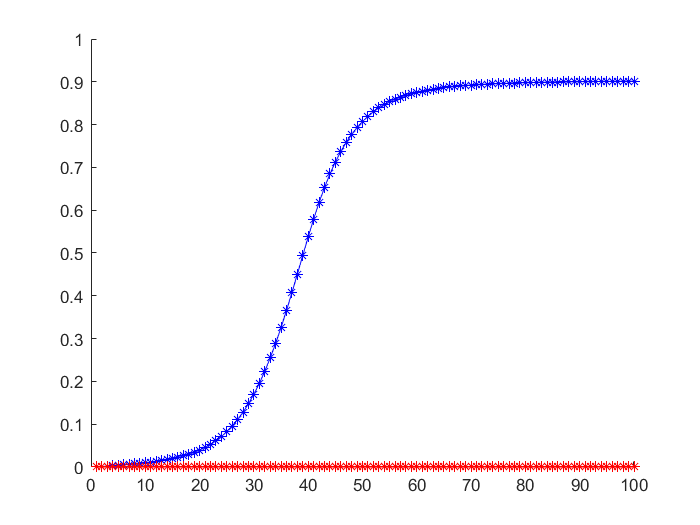


% normalizating the cross-entropy value
    en3=en3/max(en3);

% reaction time
    [peak3,t3]=find_peak_min_new(en3,thresh);
    
% plot word activation
    figure;
    hold on;
    plot(WL3(1:step,1),'b-*'); % target
    plot(WL3(1:step,2),'r-*'); % related word
    hold off;

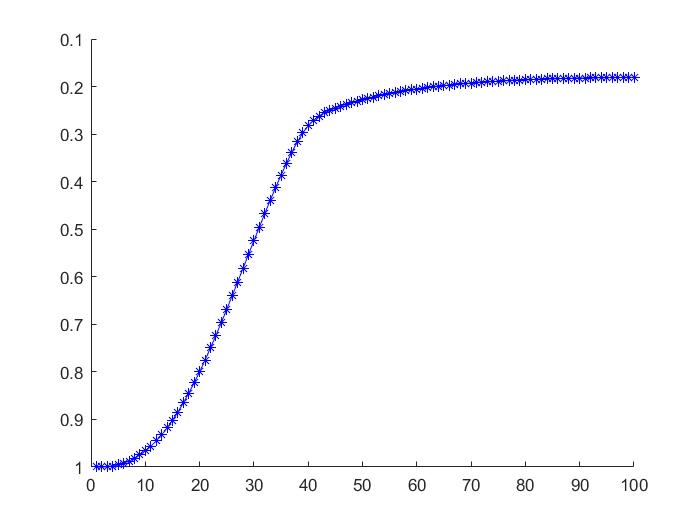


% plot semantic activation
    figure;
    hold on;
    plot(en3(1:step),'b-*'); % target
    set(gca, 'YDir','reverse')
    hold off;

        %%%%%%%%%%%%%%% Low SemD, Low Freq target %%%%%%%%%%%%%%%%

% semantics layer
    SL4=zeros(step,70);
% word layer; 
    WL4=zeros(step,11);
    % these layer matrices fill in with the activation for each unit at each step

% weights btween Semantics and Word Layer
   WLW=zeros(11,70);
    WLW(1,1:10)=LF1; 
    %WLW(2,7:10)=LF2;WLW(2,11:16)=LF2;
    %WLW(3,7:10)=LF2;WLW(3,17:22)=LF2;
    %WLW(4,7:10)=LF2;WLW(4,23:28)=LF2;
    %WLW(5,7:10)=LF2;WLW(5,29:34)=LF2;
    %WLW(6,7:10)=LF2;WLW(6,35:40)=LF2;
    %WLW(7,7:10)=LF2;WLW(7,41:46)=LF2;
    %WLW(8,7:10)=LF2;WLW(8,47:52)=LF2;
    %WLW(9,7:10)=LF2;WLW(9,53:58)=LF2;
    % WLW(10,7:10)=LF2;WLW(10,59:64)=LF2;
    % WLW(11,7:10)=LF2;WLW(11,65:70)=LF2;

    WLW5=extf*WLW

WLW5 =     0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

    WLW3=extb*WLW

WLW3 =     0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

     
% inhibitory weights
    WINWL=ones(11,11);
    WINWL=inhW*WINWL;
    for j=1:11
        WINWL(j,j)=0;
    end;
    
    WINSL=ones(70,70);
    WINSL=inhS*WINSL;
    for j=1:70
        WINSL(j,j)=0;
    end;

%initialization of cross-entropy value
    en4=zeros(step,1);

% target
    target=zeros(1,70);
    target(1:10)=1;

% cross-entroy value for the first (0) time step
    en4(1)=cee(target,SL4(1,:));
    
% input
    input=zeros(1,11);
    input(1)=ic;


for i=1:step-1
    
    SL4(i+1,:)=((WLW3'*WL4(i,:)')'+(WLRLD0*SL4(i,:)')')-(WINSL*inhkernel3(SL4(i,:)'))'; % semantics layer net input
        % for the next row of SL (next step), the input is the forward activation of the word layer plus
        % the excitatory/inhibitory inputs within the semantic layer relative to the current activation
    
    WL4(i+1,:)=((WLW5*SL4(i,:)')')+input%-(WINWL*inhkernel3(WL4(i,:)'))'; % word layer net input
        % for the next row of WL (next step), the input is the backward activation of the semantic layer plus
        % the sigmoid inhibitory effects within the word layer relative to the current activation plus
        % the current input activation (constant)
 
    SL4(i+1,:)=SL4(i,:)... % change unit activations in semantic layer
        +(SL4(i+1,:)>0).*((Fmax-SL4(i,:)).*SL4(i+1,:)-decay1.*(SL4(i,:)-rest))... % if net input>0
        +(SL4(i+1,:)<=0).*((SL4(i,:)-Fmin).*SL4(i+1,:)-decay1.*(SL4(i,:)-rest));  % if net input<=0
    
    WL4(i+1,:)=WL4(i,:)... % change unit activations in word layer
        +(WL4(i+1,:)>0).*((Fmax-WL4(i,:)).*WL4(i+1,:)-decay2.*(WL4(i,:)-rest))...
        +(WL4(i+1,:)<=0).*((WL4(i,:)-Fmin).*WL4(i+1,:)-decay2.*(WL4(i,:)-rest));   
    
    SL4(i+1,:)=max(SL4(i+1,:),0); % set minimum value to 0, just in case
    WL4(i+1,:)=max(WL4(i+1,:),0);
    
    SL4(i+1,:)=min(SL4(i+1,:),1); % set maximum value to 1
    WL4(i+1,:)=min(WL4(i+1,:),1);
    
    en4(i+1)=cee(target,SL4(i+1,:)); % updating cross entropy value, our measure of the model's success
    
end;

WL4 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL4 =    1.0e-03 *

         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0  

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0011         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0011         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

WL4 =          0         0         0         0         0         0         0         0         0         0         0
    0.0010         0         0         0         0         0         0         0         0         0         0
    0.0020         0         0         0         0         0         0         0         0         0         0
    0.0029         0         0         0         0         0         0         0         0         0         0
    0.0039         0         0         0         0         0         0         0         0         0         0
    0.0048         0         0         0         0         0         0         0         0         0         0
    0.0058         0         0         0         0         0         0         0         0         0         0
    0.0067         0         0         0         0         0         0         0         0         0         0
    0.0076         0         0         0         0         0         0         0         0         0      

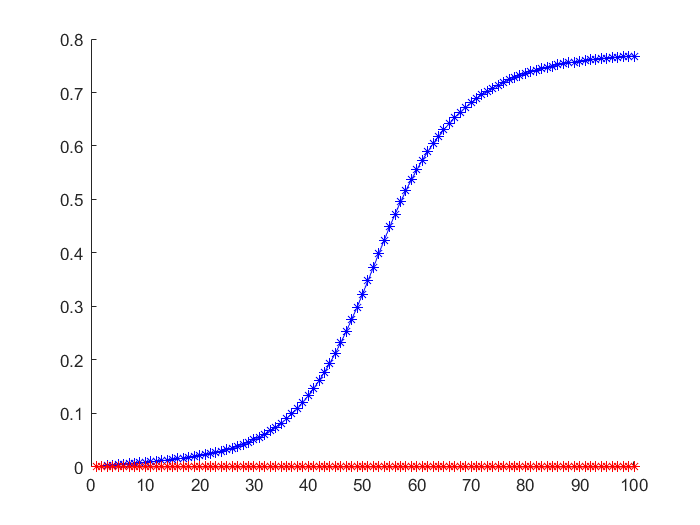


% normalizating the cross-entropy value
    en4=en4/max(en4);

% reaction time
    [peak4,t4]=find_peak_min_new(en4,thresh);
    
% plot word activation
    figure;
    hold on;
    plot(WL4(1:step,1),'b-*'); % target
    plot(WL4(1:step,2),'r-*'); % related word
    hold off;

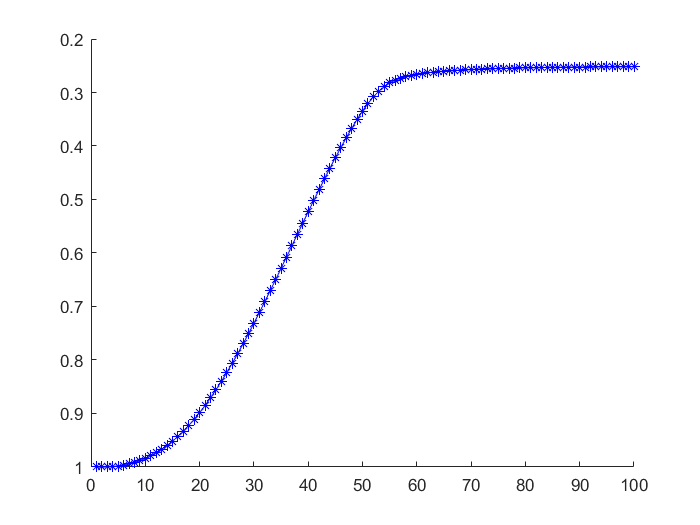


% plot semantic activation
    figure;
    hold on;
    plot(en4(1:step),'b-*'); % target
    set(gca, 'YDir','reverse')
    hold off;

%% Figure
[t1 t2 t3 t4]

ans =     36    -1    35    47


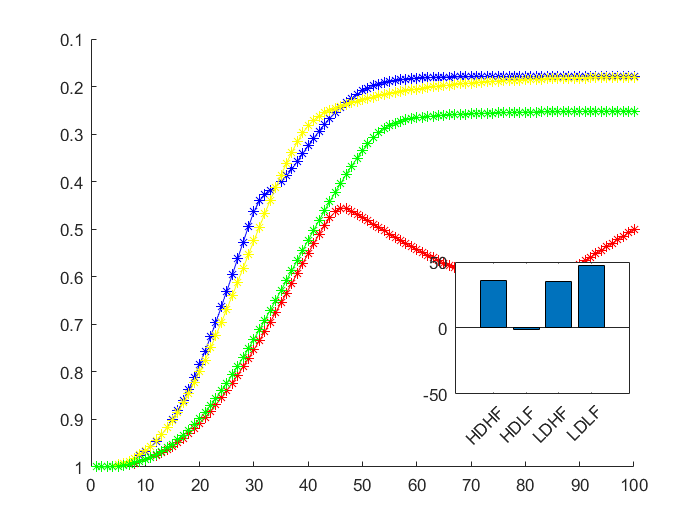


figure;
hold on;
plot(en1(1:step),'b-*'); % HDHF
plot(en2(1:step),'r-*'); % HDLF
plot(en3(1:step),'y-*'); % LDHF
plot(en4(1:step),'g-*'); % LDLF
set(gca, 'YDir','reverse')

axes('position', [.65, .25, .25, .25]);
bar([t1 t2 t3 t4]);
name = {'HDHF';'HDLF';'LDHF';'LDLF'};
set(gca,'xticklabel',name)
xtickangle(45)
hold off;